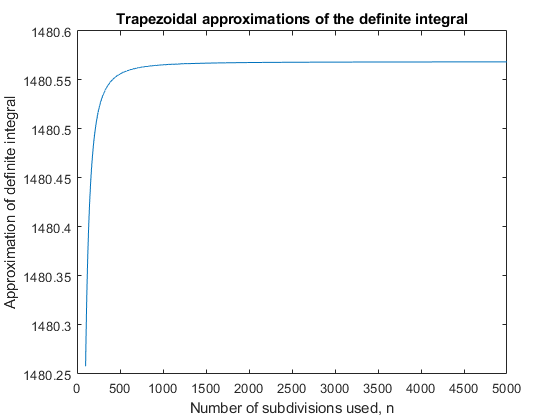

% MATLAB TEST QUESTION 1

ns = 100:5000;  % vector of n values
ints = NaN(1, length(ns));  % initializing vector of integral approximations
% loop to calculate the integral for each n value, then insert it into vector ints
for i = 1:length(ns)
    ints(i) = TRAPsolver(ns(i));
end

% plotting integral approximations vs n values
plot(ns, ints)
xlabel('Number of subdivisions used, n')
ylabel('Approximation of definite integral')
title('Trapezoidal approximations of the definite integral')

function [int] = TRAPsolver(n)
    a = 0;
    b = 30;
    dx = (b-a)/n;   % setting value of delta x using n
    xs = a : dx : b;    % creating vector of x values to use to calculate y values
    ys = (200.*(xs./(5+xs))) .* (exp((-2.*xs)./30));  % calculating y values
    y1 = ys(1 : length(ys)-1);  % this is a vector containing all f(x_i-1)
    y2 = ys(2 : length(ys));    % this is a vector containing all f(x_i)
    trapezoids = ((y1 + y2)./2) .* dx;  % this is a vector containing area of traps
    int = sum(trapezoids);   % approx. of integral is sum of areas of traps
end

I believe the true value for the definite integral to be 1480.57